# Application of the Convolution theorem: image processing  

**Yue He**

yuehe@ucsb.edu

**Convolution theorem** indicates that Fourier transform of the convolution of two functions is the product of their Fourier transforms.


$$\mathcal{F}(x_n*y_n) = X_nY_n$$


### Import image and convert it into grayscale 

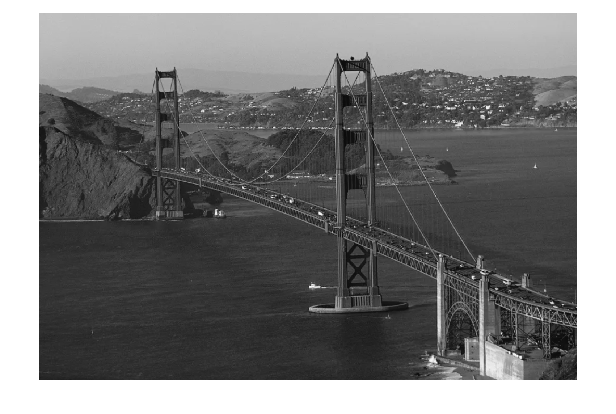

img = imread('/Users/yue/Desktop/220C lecture slides/image_test.png');
if size(img, 3) == 3
    img_gray = rgb2gray(img);
else
    img_gray = img;  
end
imshow(img_gray);

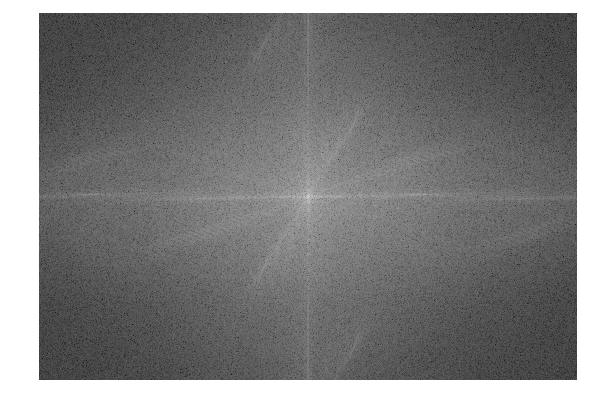


F_original = fft2(img_gray);% 2D fourier transform
F_shifted= fftshift(F_original); % Shift 0 frequency to center 
magnitude_spectrum = log(1 + abs(F_shifted));  % Using log scale to enhance visibility
imshow(magnitude_spectrum, []);

###  Low-pass filter

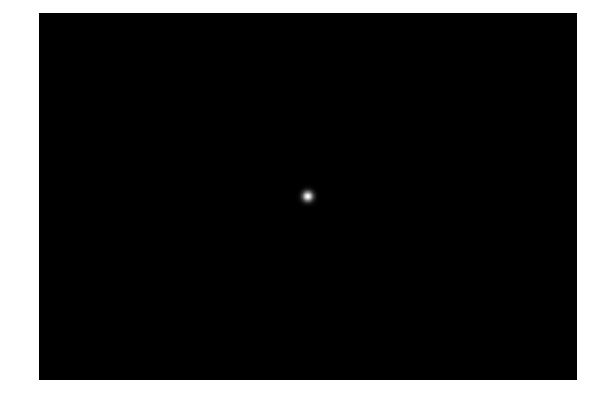

[n, m] = size(img_gray);
sigma = 10; 
[X, Y] = meshgrid(1:m, 1:n);
centerX = ceil(m/2);
centerY = ceil(n/2);
gaussianFilter = exp(-((X-centerX).^2 + (Y-centerY).^2) / (2*sigma^2));
imshow(gaussianFilter,[]);

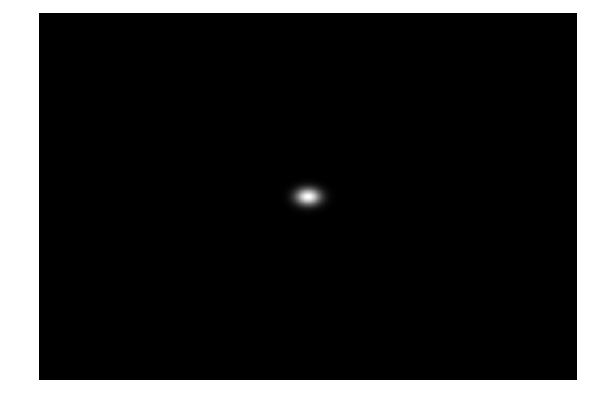


F_lowPass = fft2(gaussianFilter, n, m);
imshow(abs(fftshift(F_lowPass)) , []);

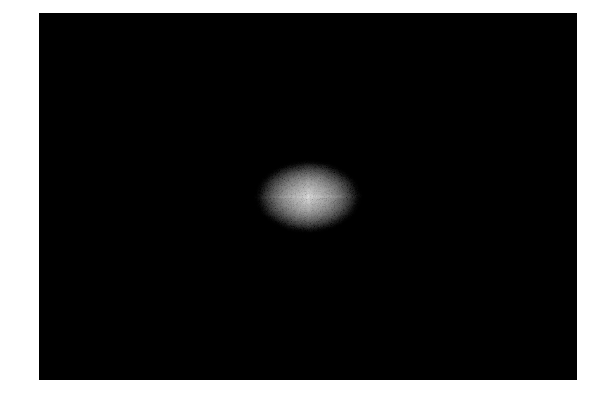


F_filtered = F_original .* F_lowPass;
imshow(log(1 + abs(fftshift(F_filtered))),[]);

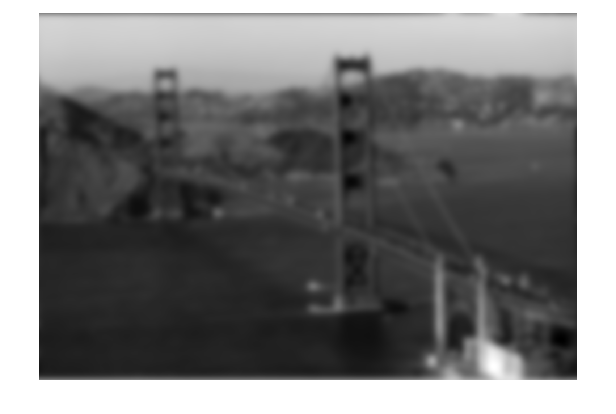

filtered_img = ifft2(F_filtered);
F_shifted2 = fftshift(filtered_img);
imshow(abs(F_shifted2), []);

### High-pass filter

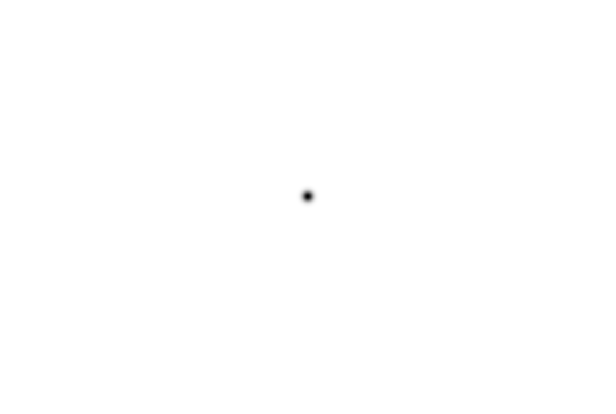

highPassFilter = 1 - gaussianFilter;
imshow(highPassFilter,[]);

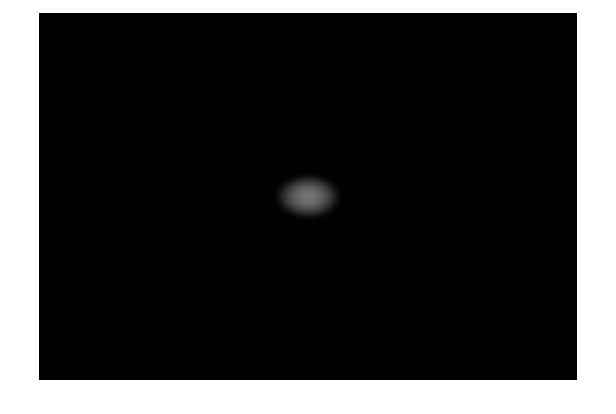


F_img = fft2(img_gray);
F_highPass = fft2(highPassFilter, n, m);
imshow(log(1 + abs(fftshift(F_highPass))),[]);

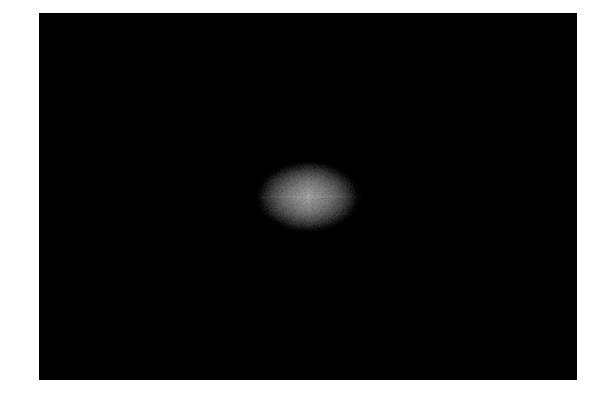


F_filtered = F_original .* F_highPass;
imshow(log(1 + abs(fftshift(F_filtered))),[]);

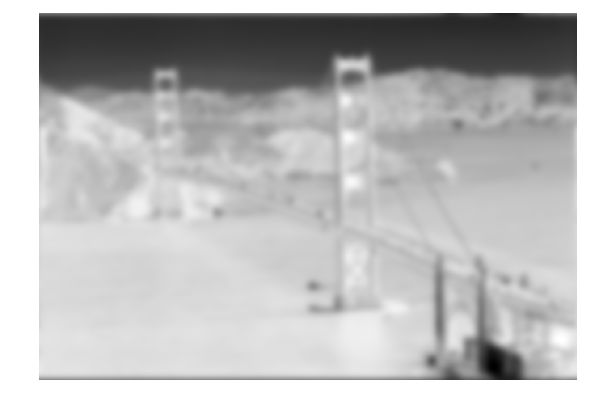

filtered_img = ifft2(F_filtered);
F_shifted3 = fftshift(filtered_img);
imshow(abs(F_shifted3), []);